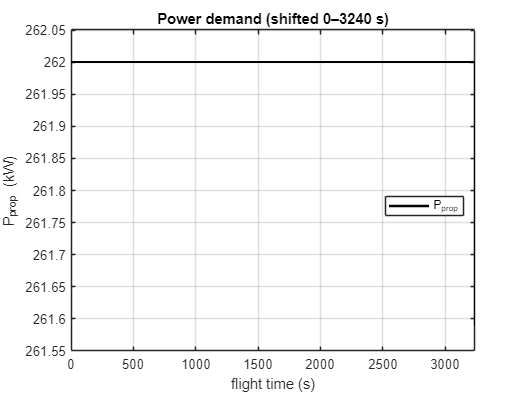

%% Plot P_prop(t) windowed to original [421, 3660] and re-zeroed to [0, 3240]
% Run the whole script once so MATLAB registers the local functions below.

t0 = linspace(0, 3240, 3241);          % new time base (s)
p0 = P_prop_0to3240(t0);               % power in W (uses your original code under the hood)

figure('Name','Power demand (shifted)');
plot(t0, p0/1000, 'k', 'LineWidth', 1.8); grid on
xlabel('flight time (s)');
ylabel('P_{prop} (kW)');
title('Power demand (shifted 0–3240 s)');
xlim([0 3240]);
legend('P_{prop}','Location','best');




%% Local function: wrapper that shifts the timeline but keeps your logic unchanged

function power = P_prop_0to3240(tprime)
% Map new domain t' ∈ [0, 3240] to original t = t' + 421 and call your original code.
    if any(tprime(:) < 0 | tprime(:) > 3240)
        error('t'' must be within 0 to 3240 seconds.');
    end
    power = P_prop_original(tprime + 421);
end

%% Your original function (unchanged)
function power = P_prop_original(t)
    T_off = 60;
    t_cruise = 420;
    t_descent = 3660;
    t_landing = 4020;
    t_taxi = 4080;
    t_final = 4440;
    
    step = 636e3;
    P_slope_1 = (262e3 - 636e3)/(t_cruise - T_off);
    P_slope_2 = (114e3 - 262e3)/(t_landing - t_descent);
    P_slope_3 = (158e3 - 114e3)/(t_taxi - t_landing);
    P_slope_4 = (40e3 - 158e3)/(t_final - t_taxi);
    
    p_ramp1 = zeros(size(t));
    p_ramp1(t >= T_off) = P_slope_1 * (t(t >= T_off) - T_off);
    
    p_ramp2 = zeros(size(t));
    p_ramp2(t >= t_cruise) = -P_slope_1 * (t(t >= t_cruise) - t_cruise);
    
    p_ramp3 = zeros(size(t));
    p_ramp3(t >= t_descent) = P_slope_2 * (t(t >= t_descent) - t_descent);
    
    p_ramp4 = zeros(size(t));
    p_ramp4(t >= t_landing) = (P_slope_3 - P_slope_2) * (t(t >= t_landing) - t_landing);
    
    p_ramp5 = zeros(size(t));
    p_ramp5(t >= t_taxi) = (P_slope_4 - P_slope_3) * (t(t >= t_taxi) - t_taxi);
    
    power = step + p_ramp1 + p_ramp2 + p_ramp3 + p_ramp4 + p_ramp5;
    power(power < 0) = 0;
end